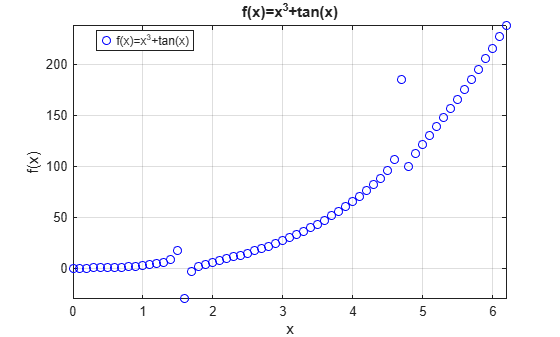

%Dovile Turauskaite
%EEf-25/2
%2026 m. rugsejo 22 d.
%2 variantas

%1. Dvimatis grafiku vaizdavimas
%a)
x=0:0.1:2*pi;
y=x.^3+tan(x);

figure(1);
plot(x,y,'bo');

title('f(x)=x^3+tan(x)');
xlabel('x');
ylabel('f(x)');
legend('f(x)=x^3+tan(x)', 'Location', 'best');
grid on;
axis ([min(x) max(x) min(y) max(y)])

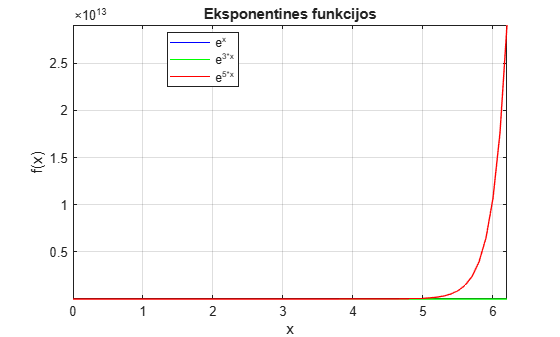

%b)
x=0:0.1:2*pi;

y1=exp(x);
y2=exp(3*x);
y3=exp(5*x);

figure(2);
plot(x, y1, 'b', x, y2, 'g', x, y3, 'r');
title('Eksponentines funkcijos');
xlabel('x');
ylabel('f(x)');
legend('e^x', 'e^{3*x}', 'e^{5*x}', 'Location', 'best');
grid on;
axis([min(x) max(x) min([y1 y2 y3]) max([y1 y2 y3])]);

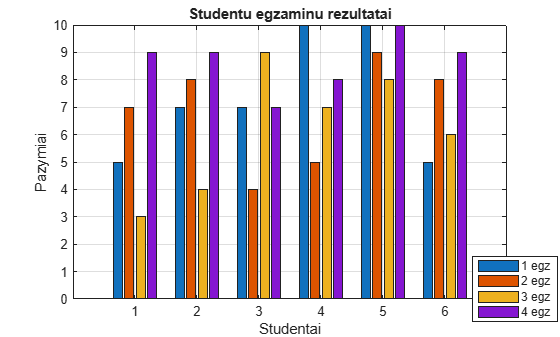

%2. Specializuotu grafiku kurimas
%a)
A=[5 7 3 9; 7 8 4 9; 7 4 9 7; 10 5 7 8; 10 9 8 10; 5 8 6 9];
figure(1);
bar(A);
title('Studentu egzaminu rezultatai');
xlabel('Studentai');
ylabel('Pazymiai');

legend('1 egz', '2 egz', '3 egz', '4 egz', 'Location','best');
axis([0 7 0 10]);
grid on;

legend(["1 egz", "2 egz", "3 egz", "4 egz"], "Position", [0.8424 0.0447 0.1546, 0.1946])

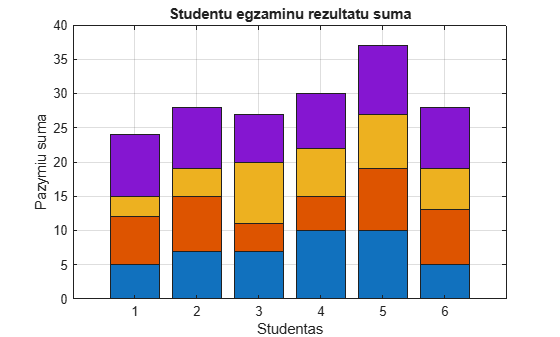

%b)
figure(2);
bar(A, 'stacked');
title('Studentu egzaminu rezultatu suma');
xlabel('Studentas');
ylabel('Pazymiu suma');

axis([0 7 0 40]);
grid on

%papildoma uzduotis
%15 variantas

A=6;
f=2;
sigma=1.5;
U1=4;
U2=2;

t=0:0.005:2;

q=A*cos(2*pi*f*t)+sigma*rand(size(t));
qf=q;
qf(abs(qf)<U2)=0;

figure;

subplot(2,1,1);

plot(t,q,'b--', 'LineWidth',1);
hold on;

plot(t, qf,'r-', 'LineWidth',1.25);

yline(U1,'k-.', 'LineWidth',1);
yline(U2, 'y-.', 'LineWidth',1);
yline(-U2, 'y.-', 'LineWidth',1);

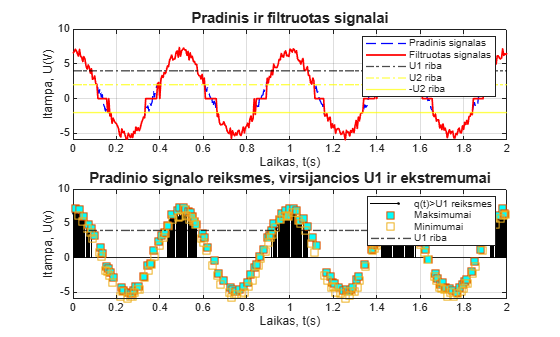


grid on;
xlim([0 2]);

xlabel('Laikas, t(s)');
ylabel('Itampa, U(V)');

title('Pradinis ir filtruotas signalai', 'FontWeight','bold', 'FontSize',11);
legend('Pradinis signalas', 'Filtruotas signalas', 'U1 riba','U2 riba', '-U2 riba');

subplot(2,1,2);
ind=q>U1;
stem(t(ind),q(ind),'k.');
hold on;

maxInd=find(q(2:end-1)>q(1:end-2)&q(2:end-1)>q(3:end))+1;
minInd=(find(q(2:end-1)<q(1:end-2)&q(2:end-1)<q(3:end))+1);

maxVal=q(maxInd);
minVal=q(minInd);

plot(t(maxInd), maxVal,'s', 'MarkerSize', 7, 'MarkerFaceColor','c');
plot(t(minInd),minVal, 's', 'MarkerSize',7);

yline(U1, 'k-.','LineWidth',1);

grid on;
xlim([0 2]);

xlabel('Laikas, t(s)');
ylabel('Itampa, U(v)');
title('Pradinio signalo reiksmes, virsijancios U1 ir ekstremumai', 'FontWeight', 'bold','FontSize',11);
legend('q(t)>U1 reiksmes', 'Maksimumai','Minimumai', 'U1 riba');